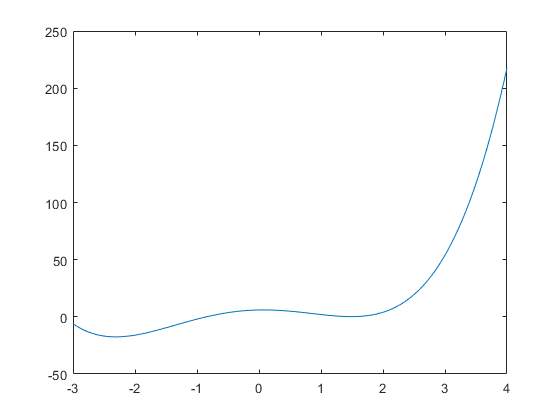

f=@(x)x.^4--x.^3-7*x.^2+x+6;
g=@(x)x.^4--x.^3-3*x.^2+11*x-6;

x=-3:0.01:4;

plot(x,f(x))


der=@(x,y)(x-y)/0.001;
x0=-1;

er=100;
i=0;


while er>10^(-10)
    i=i+1;
    o=-f(x0)/der(f(x0+0.001),f(x0));
    x0=x0+o;
    er=abs(o)./abs(x0);
end

x0

x0 = -0.8500

er

er = 3.4760e-12

i

i = 5